# HHL algorithm

clc; clear all; close all;


## Problem statement 

% A is unitary  - a function for check is needed
a = [1 -1/3;
    -1/3 1];
b= [0 1]';

x = inv(a)*b;  % 0.3750   1.1250

[v d] = eig(a);

% Integer encoding for eigen value
t=1*2*pi/d(1,1)/2^2; % N*lamba*t/2pi = 1


## Step 0 - Psi 0 

### 1)   Initial Setting

[v d] = eig(a);

temp0 = zeros(16,1);
temp0(1,1) = 1;
state0 = quantum.gate.QuantumState(temp0);

state0.formula;

text0 = sprintf('|psi_0> = %s', state0.formula);
disp(text0)

|psi_0> = 1 * |0000>


## Step I - Psi 1 

#### 1) : Set "b"

gate01 = [xGate(1); idGate(2:4)];
c01 = quantumCircuit(gate01,Name='Step1');
state01 = simulate(c01,state0);

state01.formula;

text1 = sprintf('|psi_1> = %s', state01.formula);
disp(text1)

|psi_1> = 1 * |1000>


## Step II - Psi 2  

#### 1) H gate for A - Superposition

#### 2) Eigen vector transformation for "b"

gate02 = [idGate(1); hGate(2:3); idGate(4)];
c02 = quantumCircuit(gate02,Name='Step2');
state02 = simulate(c02,state01);

state02.formula;

text2 = sprintf('|psi_2> = %s', state02.formula("Basis",'Z'));
disp(text2)

|psi_2> = 0.5 * |1000> +
0.5 * |1010> +
0.5 * |1100> +
0.5 * |1110>



% eigen vector-based transformation of b

check = -v(:,1)/sqrt(2)+v(:,2)/sqrt(2)

check =          0
    1.0000



state02_01 = state02;
state02_02 = state02;

state02_01.Amplitudes = [1 0 1 0 1 0 1 0 0 0 0 0 0 0 0 0]'/sqrt(2)*-1;
state02_02.Amplitudes = state02.Amplitudes/sqrt(2)*1;


text2_01 = sprintf('|psi_2_01> = %s', state02_01.formula("Basis",'Z'));
disp(text2_01)

|psi_2_01> = -0.70711 * |0000> +
-0.70711 * |0010> +
-0.70711 * |0100> +
-0.70711 * |0110>



text2_02 = sprintf('|psi_2_02> = %s', state02_02.formula("Basis",'Z'));
disp(text2_02)

|psi_2_02> = 0.35355 * |1000> +
0.35355 * |1010> +
0.35355 * |1100> +
0.35355 * |1110>


## Step III - Psi 3

### 1) Sheorinder equation-based transformation for b


$$U\ket{b}  == e^{2\pi\cdot i \cdot \phi } \cdot \ket{b}$$


# 
$$\phi {\;}_j =\frac{k\cdot \lambda {\;}_{j\;} \cdot t}{2\pi \;}$$


$\frac{N\cdot \lambda_i \cdot t}{2\pi}=1$ for Integer mapping , when $\lambda_1 \rightarrow 1$  so $t = \frac{3\pi}{2}$

state03_01 = state02_01;
state03_02 = state02_02;

state03_01.Amplitudes = [-1 0 -i 0 1 0 i 0 0 0 0 0 0 0 0 0]'/2/sqrt(2);
state03_02.Amplitudes = [0 0 0 0 0 0 0 0 1 0 -1 0 1 0 -1 0]'/2/sqrt(2);

text3_01 = sprintf('|psi_3_01> = %s', state03_01.formula("Basis",'Z'));
disp(text3_01)

|psi_3_01> = (-0.35355+0i) * |0000> +
(0+0.35355i)  * |0010> +
(0.35355+0i)  * |0100> +
(0-0.35355i)  * |0110>



text3_02 = sprintf('|psi_3_02> = %s', state03_02.formula("Basis",'Z'));
disp(text3_02)

|psi_3_02> = 0.35355  * |1000> +
-0.35355 * |1010> +
0.35355  * |1100> +
-0.35355 * |1110>


## Step IV - Psi 4

### 1) Inverse QFT

gate04 = [idGate(1); 
          qftGate(2:3);
          idGate(4)
         ];

c04 = quantumCircuit(gate04,Name="Step4_iQFT");

state04_01 = simulate(c04,state03_01);
state04_02 = simulate(c04,state03_02);

% Normalizing for two v1, v2
state04_01.Amplitudes = state04_01.Amplitudes/sqrt(2);
state04_02.Amplitudes = state04_02.Amplitudes/sqrt(2);

text4_01 = sprintf('|psi_4_01> = %s', state04_01.formula("Basis",'Z'));
disp(text4_01)

|psi_4_01> = (-0.70711+2.1649e-17i) * |0010>



text4_02 = sprintf('|psi_4_02> = %s', state04_02.formula("Basis",'Z'));
disp(text4_02)

|psi_4_02> = 0.70711 * |1100>


## Step V - Psi 5 

### 1) Rotation of Anchilla 

: Unsolve Entanglement

% theta_1 = 2arcsin(1/1)
gate05_01 = [idGate(1:3);
             ryGate(4,pi);
            ];

% theta_2 = 2arcsin(1/2)
gate05_02 = [idGate(1:3);
             ryGate(4,pi/3);
            ];

c05_01 = quantumCircuit(gate05_01,Name='Anchilla_Rotation_1');
c05_02 = quantumCircuit(gate05_02,Name='Anchilla_Rotation_2');


state05_01 = simulate(c05_01,state04_01);
state05_01.Amplitudes = state05_01.Amplitudes *sqrt(8/5)/sqrt(2);
state05_01.formula('Basis','z');

state05_02 = simulate(c05_02,state04_02);
state05_02.Amplitudes = state05_02.Amplitudes *sqrt(8/5)/sqrt(2);
% state05_02.Amplitudes(13) = 0;
state05_02.formula('Basis','z');

text5_01 = sprintf('|psi_5_01> = %s', state05_01.formula("Basis",'Z'));
disp(text5_01)

|psi_5_01> = (-0.89443+2.7384e-17i) * |0011>



text5_02 = sprintf('|psi_5_02> = %s', state05_02.formula("Basis",'Z'));
disp(text5_02)

|psi_5_02> = 0.7746  * |1100> +
0.44721 * |1101>


## Step VI - Psi 6

### 1) Measurement only for anchilla qubit 1


state06_01 = state05_01; 
state06_02 = state05_02;

state06_02.Amplitudes(13) = 0;

text6_01 = sprintf('|psi_6_01> = %s', state06_01.formula("Basis",'Z'));
disp(text6_01)

|psi_6_01> = (-0.89443+2.7384e-17i) * |0011>



text6_02 = sprintf('|psi_6_02> = %s', state06_02.formula("Basis",'Z'));
disp(text6_02)

|psi_6_02> = 0.44721 * |1101>


## Step VII - Psi 7

### 1) Inverse QFT

gate07 = [idGate(1); 
         qftGate(2:3);
         idGate(4);
         ];

c07 = quantumCircuit(gate07,Name='Inverse_QFT');

state07_01 = simulate(c07,state06_01);
state07_01.Amplitudes = state07_01.Amplitudes*sqrt(8/5)/sqrt(2);
state07_01.formula('Basis','Z');

state07_02 = simulate(c07,state06_02);
state07_02.Amplitudes = state07_02.Amplitudes*sqrt(8/5)/sqrt(8);
state07_02.formula('Basis','Z');

text7_01 = sprintf('|psi_7_01> = %s', state07_01.formula("Basis",'Z'));
disp(text7_01)

|psi_7_01> = (-0.44721-1.2823e-34i) * |0001> +
(-5.4768e-17-0.44721i) * |0011> +
(0.44721+3.2636e-34i)  * |0101> +
(5.4768e-17+0.44721i)  * |0111>



text7_02 = sprintf('|psi_7_02> = %s', state07_02.formula("Basis",'Z'));
disp(text7_02)

|psi_7_02> = 0.22361  * |1001> +
-0.22361 * |1011> +
0.22361  * |1101> +
-0.22361 * |1111>


## Step VIII - Psi 8

### 1) Inverse 


$$U\cdot \ket{b} ==e^{i \cdot \lambda_j \cdot t} \cdot \ket{u_i} $$


from


$$\ket{\psi_4} == \sum^{2^{n_b} -1}_{j=0} b_j \cdot \ket{u_j} \ket{} \ket{N \lambda_j t /2 \pi}   \ket{0}_a $$


So 


$$ \sum^{2^{n_b} -1}_{j=0} b_j \cdot \ket{u_j} \ket{} \ket{N \lambda_j t /2 \pi}   \ket{0}_a \rightarrow \ket{\psi_8}$$


state08_01 = state07_01;
state08_02 = state07_02;

state08_01.Amplitudes = [0 1 0 1 0 1 0 1 0 0 0 0 0 0 0 0]'*(1/2)*(sqrt(8/5))*(-3/2)/sqrt(2);
state08_02.Amplitudes = [0 0 0 0 0 0 0 0 0 1 0 1 0 1 0 1]'*(1/2)*(sqrt(8/5))*(3/4)/sqrt(2);

text8_01 = sprintf('|psi_8_01> = %s', state08_01.formula("Basis",'Z'));
disp(text8_01)

|psi_8_01> = -0.67082 * |0001> +
-0.67082 * |0011> +
-0.67082 * |0101> +
-0.67082 * |0111>



text8_02 = sprintf('|psi_8_02> = %s', state08_02.formula("Basis",'Z'));
disp(text8_02)

|psi_8_02> = 0.33541 * |1001> +
0.33541 * |1011> +
0.33541 * |1101> +
0.33541 * |1111>


## Step IX - Psi 9

### 1) Inverse H transporation

### 2) $\ket{u_i} \\ \rightarrow \ket{b}$

## 
$$\ket{u_0} == \frac{-1}{\sqrt{2}} \ket{0} \\ + \frac{-1}{\sqrt{2}} \ket{1}$$



$$\ket{u_1} == \frac{-1}{\sqrt{2}} \ket{0} \\ + \frac{1}{\sqrt{2}} \ket{1}$$


gate09 = [idGate(1); hGate(2:3); idGate(4)];

c09 = quantumCircuit(gate09,Name='Inverse_H');

state09_01 = simulate(c09,state08_01);
state09_02 = simulate(c09,state08_02);

state09_01.Amplitudes=state09_01.Amplitudes*(2/3)*(sqrt(8/5))*(-3/2)/sqrt(2);
state09_02.Amplitudes = state09_02.Amplitudes*(2/3)*(sqrt(8/5))*(3/4)/sqrt(2);

state09_01.formula('Basis','z');
state09_02.formula('Basis','z');

state09_03 = state09_01;
state09_03.Amplitudes=zeros(1,16)';

state09_03.Amplitudes(2)=(1/2)*(sqrt(2/5));
state09_03.Amplitudes(10) = (1/2)*(sqrt(2/5))*3;



text09 = sprintf('|psi_9> = %s', state09_03.formula("Basis",'Z'));
disp(text09)

|psi_9> = 0.31623 * |0001> +
0.94868 * |1001>


## Answer

p1 = probability(state09_03,1,'0');
p2 = probability(state09_03,1,'1');

% so, -1/3s1+3s1=1;

s1 = 1/(3-1/3);
s2 = s1*sqrt(p2/p1);

text_s1 = sprintf('The first solution is %s', s1 );
disp(text_s1)

The first solution is 3.750000e-01



text_s2 = sprintf('The second solution is %s', s2 );
disp(text_s2)

The second solution is 1.125000e+00


## Step - Final

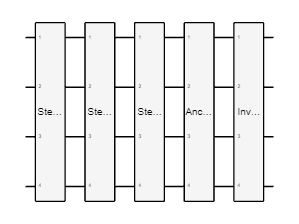

gate_all = [compositeGate(c01,[1:4]); 
            compositeGate(c02,[1:4]);
            compositeGate(c04,[1:4]);
            compositeGate(c05_01,[1:4]);
            compositeGate(c07,[1:4]);
            compositeGate(c09,[1:4]);
            ];

c_all = quantumCircuit(gate_all);

figure(1);
set(gcf,'color',[1 1 1]);
plot(c_all);
title('<HHL circuit>');

## Step -